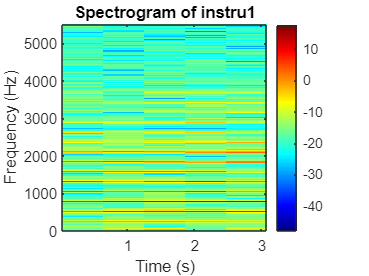


[y1, Fs] = audioread('instru1.wav');
window_length = 7250;  
overlap = 512;        
nfft = 7250;           
[S, f, t] = spectrogram(y1, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  
colormap('jet');  
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of instru1');
colorbar; 

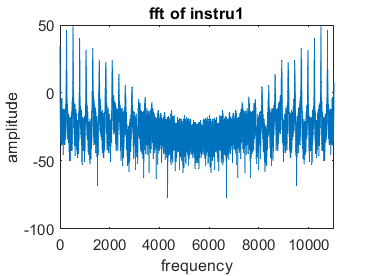

figure;
fft_opera=abs(fft(y1));
freqs = (0:length(fft(y1))-1) * (Fs /length(fft(y1))); Freq=freqs;
plot(Freq,20*log10(fft_opera))
title("fft of instru1")
xlabel("frequency")
ylabel("amplitude")

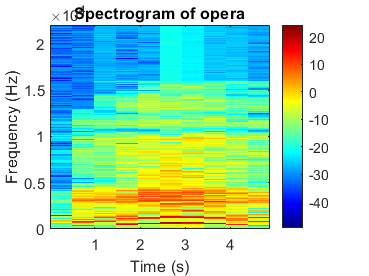



[y2, Fs] = audioread('Opera.wav');
window_length = 22000;  
overlap = 512;         
nfft = 22000;           
[S, f, t] = spectrogram(y2, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  
colormap('jet');  
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of opera');
colorbar;  

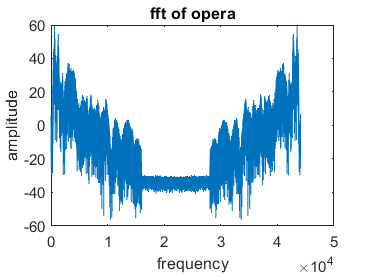

figure;
fft_opera=abs(fft(y2));
freqs = (0:length(fft(y2))-1) * (Fs /length(fft(y2))); Freq=freqs;
plot(Freq,20*log10(fft_opera))
title("fft of opera")
xlabel("frequency")
ylabel("amplitude")